# Algoritmos Numéricos por Computadora

# Segundo parcial - Primavera 2020

Cambia el nombre del script a Nombre (ej: Marcelo).

Sube tu archivo resultado a comunidad $\to$ Segundo parcial antes de las 10am del domingo 5 de abril.

Al correr tu script deben desplegarse los resultados. Por lo tanto, debes escribir al final del script todas las funciones que usas.

El examen es individual, debes resolverlo sin ayuda de ninguna persona. 

Revisa con mucho cuidado tus respuestas. El examen será calificado de manera muy estricta.

## 1. Inversa de una matriz

Usa la función `[L,U,P] = lu(A)` de Matlab para invertir la matriz 


$$A=\left\lbrack \begin{array}{ccc}
4 & -1 & 0\\
-1 & 4 & -1\\
0 & -1 & 4
\end{array}\right\rbrack$$


Recuerda que la columna j de $A^{-1}$ es la solución del sistema $\textrm{Ax}=b$ donde b es la columna j de la matriz identidad (permutada por P). Puedes usar el operador "backslash" para resolver los sistemas Ly=b y Ux=y. 

A = [4 -1 0; -1 4 -1; 0 -1 4]

A =      4    -1     0
    -1     4    -1
     0    -1     4


[n,m] = size(A);
A_inv = zeros(n,m);
[L,U,P] = lu(A);
for i=1:n
    b = P(:,i);
    y = L\b;
    A_inv(:,i) = U\y;
end
%Comprobamos
A_inv

A_inv =     0.2679    0.0714    0.0179
    0.0714    0.2857    0.0714
    0.0179    0.0714    0.2679


inv(A)

ans =     0.2679    0.0714    0.0179
    0.0714    0.2857    0.0714
    0.0179    0.0714    0.2679


## 2. Algoritmo de Gauss-Seidel 

Utiliza tu algoritmo de Gauss-Seidel (cópialo más abajo) para resolver el sistema Ax = b, donde:


$$A=\left\lbrack \begin{array}{ccc}
0\ldotp 1 & 7 & -0\ldotp 3\\
3 & -0\ldotp 1 & -0\ldotp 2\\
0\ldotp 3 & -0\ldotp 2 & 10
\end{array}\right\rbrack$$



$$b=\left\lbrack \begin{array}{c}
-19\ldotp 3\\
7\ldotp 85\\
71\ldotp 4
\end{array}\right\rbrack$$


Como la matriz A no es diagonal dominante, debes intercambiar los renglones 1 y 2 de A (y de b) para que el método converja. 

Escribe aquí la matriz P de permutación (no tiene nada que ver con LU)

P = [0 1 0; 1 0 0; 0 0 1];

Intercambia aquí los renglones de A y b usando P

A = [0.1 7 -0.3; 3 -0.1 -0.2; 0.3 -0.2 10];
b = [-19.3; 7.85; 71.4];

pA = P*A,

pA =     3.0000   -0.1000   -0.2000
    0.1000    7.0000   -0.3000
    0.3000   -0.2000   10.0000


pb = P*b;

Resuelve el sistema de ecuaciones.

[x,i] = gaussSeidel4(pA,pb)

x =     3.0000
   -2.5000
    7.0000


i = 10

% para comprobar:
A\b

ans =     3.0000
   -2.5000
    7.0000


## 3. Algoritmo de gradiente conjugado

Este algoritmo $x_{i+1} =x_i +\alpha_i d_i$ minimiza el problema cuadrático:

$f\left(x\right)=\frac{1}{2}x^{\prime } \textrm{Ax}-b^{\prime } x+c$  (A es positiva definida)

en n (o menos) pasos ( n = length(x) ) tomando direcciones de descenso determinadas por vectores que son A-conjugados:

 *u* y *v* son A-conjugados si $u^{\prime } \textrm{Av}=0$  ( en lugar de $u^{\prime } \textrm{Iv}=u^{\prime } v=\;\textrm{dot}\left(u,v\right)\;=0\;$)

El tamaño del paso en cada iteración es


$$\alpha_i =\frac{r_i^{\prime } \;r_i }{d_i^{\prime } Ad_i }$$


La primera dirección *d* de descenso es


$$d_0 \;=r_0 =b-Ax_0$$


y las siguientes se calculan como


$$d_{i+1} =r_{i+1} +\frac{r_{i+1}^{\prime } r_{i+1} }{r_i^{\prime } r_i }d_i$$


Programa (más abajo), de manera **eficiente** y **elegante**, el método del gradiente conjugado. El método debe usar el **mismo** criterio de salida del while que el de descenso máximo para poder compararlos.

Prueba el método en el siguiente espacio con el sistema Ax = b, donde:


$$A=\left\lbrack \begin{array}{ccc}
4 & -1 & 0\\
-1 & 4 & -1\\
0 & -1 & 4
\end{array}\right\rbrack$$



$$b=\left\lbrack \begin{array}{c}
2\\
6\\
2
\end{array}\right\rbrack$$


 Usa el vector x0=zeros(3,1) como valor inicial. 

x0 = zeros(3,1);
A = [4 -1 0; -1 4 -1; 0 -1 4];
b = [2;6;2];


Compara el número de iteraciones de este método con el de descenso máximo.

[x1,i1] = gradienteConjugado(A,b,x0);
[x2,i2] = steepestDescent(A,b,x0);

fprintf('Iteraciones en gradiente conjugado: %i',i1)

Iteraciones en gradiente conjugado: 2

fprintf('Iteraciones decenso máximo: %i',i2)

Iteraciones decenso máximo: 26

%Se puede notar que gradiente conjugado es muchísimo más rápido que decenso
%máximo ya que iteró 2 veces en comparación a las 26 veces que iteró
%decenso. En este ejemplo no se puede ver tan claro por la simplicidad del
%sistema que se buscaba resolver, pero con matrices más complicadas i2
%puede llegar a exceder el máximo de iteraciones y seguir sin converger.

## 4. Sistema de ecuaciones no lineales

Determina (todos) los puntos de intersección entre la circunferencia con centro en el origen y radio $\sqrt{3}$  y la hipérbola xy = 1.

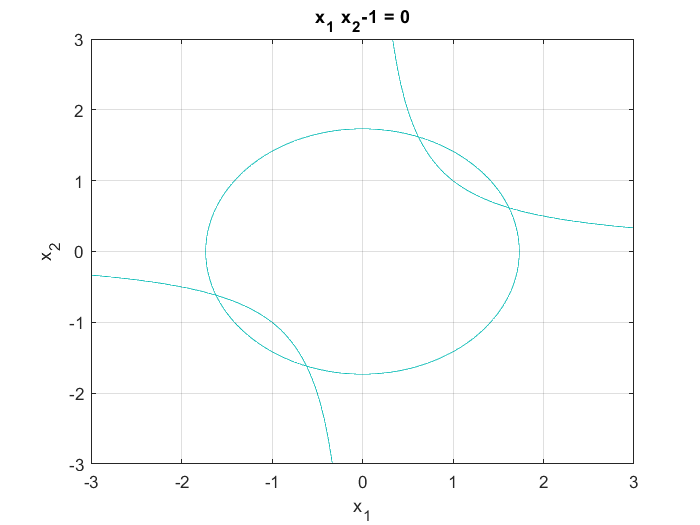

f = @(x)[x(1)^2+x(2)^2-3;
         x(1)*x(2)-1];
    
%Sabemos que el centro de la circunferencia está en el origen y debido a
%que su radio es = sqrt(3) =  1.7321 aprox, el contorno del círculo va a
%ser menor que dos. Graficamos para encontrar la cantidad de intesecciones
%que tienen las dos figuras.

f1 = @(x1,x2) x1.^2 + x2.^2 -3;
f2 = @(x1,x2) x1.*x2 -1;
ezplot(f1,[-3,3])
grid on
hold on
ezplot(f2,[-3,3])
hold off


%Estamos buscando 4 puntos entonces debemos correr NewtonRaphsonVV 4 veces
%en diferentes regiones. Iremos de izquierda a derecha.
a = -2;
b = -1;

x01 = [a ; b];
[x1,i1] = NewtonRaphsonVV(f,x01) %Mi función NewtonRaphsonVV calcula el jacobiano

x1 =    -1.6180
   -0.6180


i1 = 6


x02 = [b ; a];
[x2,i2] = NewtonRaphsonVV(f,x02)

x2 =    -0.6180
   -1.6180


i2 = 6


x03 = -x02;
[x3,i3] = NewtonRaphsonVV(f,x03)

x3 =     0.6180
    1.6180


i3 = 6


x04 = -x01;
[x4,i4] = NewtonRaphsonVV(f,x04)

x4 =     1.6180
    0.6180


i4 = 6

## 5. Vectores

Considera los vectores siguientes:

$\begin{array}{l}
\overrightarrow{A} =2\overrightarrow{i} -3\overrightarrow{j} +a\overrightarrow{k} \\
\overrightarrow{B} =b\overrightarrow{i} +1\overrightarrow{j} -4\overrightarrow{k} \\
\overrightarrow{C} =3\overrightarrow{i} +c\overrightarrow{j} +2\overrightarrow{k} 
\end{array}$El vector$\overrightarrow{A}$es perpendicular al vector$\overrightarrow{B}$y al vector$\overrightarrow{C}$. También se sabe que$\overrightarrow{B} \cdot \overrightarrow{C} =2\ldotp$

Encuentra los valores de las tres incognitas: $a$, $b$ y $c$.

%Declaramos las variables simbólicas a, b y c
syms a b c ;
A = [2, -3, a];
B = [b, 1, 4];
C = [3, c, 2];

%Según las condiciones, calculamos los productos punto para obtener
%ecuaciones en términos de a, b y c
pAB = dot(A,B) == 0

$$pAB = 2\,b+4\,\bar{a}-3=0$$

pAC = dot(A,C) == 0

$$pAC = 2\,\bar{a}-3\,c+6=0$$

pBC = dot(B,C) == 2

$$pBC = c+3\,\bar{b}+8=2$$


%Tomamos los coeficientes de los productos punto para sustituirlos en la
%matriz y las constantes en b y de esta forma encontrar la solución
M = [4 2 0; 2 0 -3; 0 3 1]

M =      4     2     0
     2     0    -3
     0     3     1


t = [3;-6;-6]

t =      3
    -6
    -6


% x contiene el valor de las incógnitas a,b,c
x = M\t;

% Ahora sustituimos en las matrices originales para comprobar los
% resultados
As = double(subs(A,a,x(1)));

As =     2.0000   -3.0000    2.3438


Bs = double(subs(B,b,x(2)));

Bs =    -3.1875    1.0000    4.0000


Cs = double(subs(C,c,x(3)));

Cs =     3.0000    3.5625    2.0000



%Deben ser iguales a cero
dot(As,Bs)

ans = 0

dot(As,Cs)

ans = 0


%Debe ser igual a 2
dot(Bs,Cs)

ans = 2

## 6. Uso de Matlab

Dada una matriz cuadrada A, escribe una instrucción Matlab de un solo renglon que cree una nueva matriz Aug que consista en la matriz original aumentada por una matriz identidad. Por ejemplo, si


$$A=\left\lbrack \begin{array}{ccc}
0\ldotp 1 & 7 & -0\ldotp 3\\
3 & -0\ldotp 1 & -0\ldotp 2\\
0\ldotp 3 & -0\ldotp 2 & 10
\end{array}\right\rbrack$$


entonces


$$\textrm{Aug}=\left\lbrack \begin{array}{cccccc}
0\ldotp 1 & 7 & -0\ldotp 3 & 1 & 0 & 0\\
3 & -0\ldotp 1 & -0\ldotp 2 & 0 & 1 & 0\\
0\ldotp 3 & -0\ldotp 2 & 10 & 0 & 0 & 1
\end{array}\right\rbrack$$


A = [0.1 7 -0.3; 3 -0.1 -0.2; 0.3 -0.2 10];
Aug = [A eye(size(A))]

Aug =     0.1000    7.0000   -0.3000    1.0000         0         0
    3.0000   -0.1000   -0.2000         0    1.0000         0
    0.3000   -0.2000   10.0000         0         0    1.0000


Copia aquí tu funcion Gauss Seidel

function [x,i] = gaussSeidel4(A, b)
tol = eps;
D = diag(diag(A));
L = tril(A,-1);
x = zeros(size(b));
max_iters = 1000;
i = 0;
cond = true;

while cond
    xp = x;
    r = b - A*x;
    M = D+L;
    x = xp + M\r;
    i = i+1;
    cond = norm((x-xp)./x) > tol && i<max_iters;
end
end

Copia aquí tu funcion de descenso máximo 

function [x,i] = steepestDescent(A,b,x0)
tol = eps;
x = x0;
i = 1;
cond = true;
max_iters = 5000;
rk = b - A*x;
while cond
    xp = x;
    alpha = dot(rk',rk)/(rk'*A*rk);
    x = xp + alpha*rk;
    i = i+1;
    rk = b-A*x;
    cond = norm((x-xp)./x) > tol && i<max_iters && all(rk);
end
end

Escribe aquí tu función gradiente conjugado

function [x,i] = gradienteConjugado(A,b,x0)
max_iters = 5000;
cond = true;
tol = eps;
i = 0;

x = x0;
r  = b - A*x;
d = r;
while cond
   xp = x;
   rp = r;
   dp = d;
   alfa = (rp'*rp)/(dp'*A*dp);
   x = xp + alfa*dp;
   r = b - A*x;
   d = r + ((r'*r)/(rp'*rp))*dp;
   i = i+1;
   cond = norm((x-xp)./x) > tol && i<max_iters && all(r);
end
    
end

Copia aquí tu función Newton de varias variables

function [x,i] = NewtonRaphsonVV(f,x0)
[m,n] = size(x0);
xs = sym('x',[1 m]);
fx = f(xs);
Js= jacobian(fx,xs);
x = x0;
max_iters = 1000;
tol  = eps;
condicion = true;
i = 0;
while condicion
    xp = x;
    J  = double(subs(Js,xs,xp'));
    x = xp - J\f(xp);
    i = i+1;
    condicion = norm((x-xp)./x) > tol && i<max_iters;
end
end